## [ARX Time Series Model](https://apmonitor.com/pds/index.php/Main/ARXTimeSeries)

An ARX model is a combination of an autoregressive model (AR) and an exogenous input model (X). It is used to represent the dynamics of a system and is commonly used in control engineering to model and analyze dynamic systems.

An autoregressive model is a type of statistical model that represents a time series as a linear combination of its past values and a stochastic process. It is represented by the following equation:


$$y\left(t\right)=c+a_1 y\left(t-1\right)+a_2 y\left(t-2\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +a_p y\left(t-p\right)+e\left(t\right)$$


where *y(t)* is the value of the time series at time *t*, *c* is a constant term, *a**1*, *a**2*, ..., *a**p* are the autoregressive coefficients, *y(t-1)*, *y(t-2)*, ..., *y(t-p)* are the past values of the time series, and *e(t)* is a random error term.

An exogenous input model represents a time series as a linear combination of its past values and a set of exogenous (i.e., external) input variables. It is represented by the following equation:


$$y\left(t\right)=c+b_1 u_1 \left(t\right)+b_2 u_2 \left(t\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +b_q u_q \left(t\right)+e\left(t\right)$$


where *y(t)* is the value of the time series at time *t*, *c* is a constant term, *u**1**(t)*, *u**2**(t)*, ..., *u**q**(t)* are the exogenous input variables, and *b**1*, *b**2*, ..., *b**q* are the coefficients that capture the relationship between the input variables and the output.

An ARX model is a combination of an AR model and an X model, and it is represented by the following equation:


$$y\left(t\right)=c+a_1 y\left(t-1\right)+a_2 y\left(t-2\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +a_p y\left(t-p\right)+b_1 u_1 \left(t\right)+b_2 u_2 \left(t\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +b_q u_q \left(t\right)+e\left(t\right)$$


ARX time series models are a linear representation of a dynamic system in discrete time. Putting a model into ARX form is the basis for many methods in process dynamics and control analysis. Below is the time series model with a single input and single output with *k* as an index that refers to the time step.


$$y_{k+1} =\sum_{i=1}^{n_a } a_i y_{k-1+1} +\sum_{i=1}^{n_b } b_i u_{k-1+1}$$


With *n**a*=3, *n**b*=2, *n**u*=1, and *n**y*=1 the time series model is:


$$y_{k+1} =a_1 y_k +a_2 y_{k-1} +a_3 y_{k-2} +b_1 u_k +b_2 u_{k-1}$$


There may also be multiple inputs and multiple outputs such as when *n**a*=1, *n**b*=1, *n**u*=2, and *n**y*=2.


$${\mathrm{y1}}_{k+1} =a_{1,1} {\;\;\mathrm{y1}}_k \;+b_{1,1\;} {\mathrm{u1}}_k +b_{1,2} \;{\mathrm{u2}}_k$$



$${\mathrm{y2}}_{k+1} =a_{1,2} {\;\mathrm{y2}}_k +b_{2,1} \;{\mathrm{u1}}_k +b_{2,2\;} {\mathrm{u2}}_k$$


Time series models are used for identification and advanced control. It has been in use in the process industries such as chemical plants and oil refineries since the 1980s. Model predictive controllers rely on dynamic models of the process, most often linear empirical models obtained by system identification.

# System Identification Toolbox Method 

%%%%Retrieve Data for Timetable (tt)
url = 'http://apmonitor.com/do/uploads/Main/tclab_dyn_data2.txt'

url = 'http://apmonitor.com/do/uploads/Main/tclab_dyn_data2.txt'

websave('data_arx', url);
arx_data = readtable('data_arx');
%%%Extract time
tt = arx_data.Time

tt =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



%%%% Create coefficents for the ARX model  
A1 = [1 0.36788 0.36788]

A1 =     1.0000    0.3679    0.3679


A = cell(2,2); 		
A{1,1} = [1 -0.36788];	
A{1,2} = [0 -0.36788];
A{2,1} = [0 -0.223]; 	
A{2,2} = [1 0.136];
B1 = [0.63212 0.18964]

B1 =     0.6321    0.1896




B = cell(2,2);
%B{1,2} = [0.63212 0.18964];	
B{2,1} = [0.18964];
B{1,1} = [0.63212];
B{2,2} = [1.26420];
B{1,2} = [0.18964];
%B{2,2} = [0];

A2 = [1 0.223 -0.136]  

A2 =     1.0000    0.2230   -0.1360


B2 = [0.18964 1.26420]

B2 =     0.1896    1.2642



sys0 = idpoly(A,B)

sys0 =
Discrete-time ARX model:                                                    
  Model for output number 1: A(z)y_1(t) = - A_i(z)y_i(t) + B(z)u(t) + e_1(t)
    A(z) = 1 - 0.3679 z^-1                                                  
                                                                            
    A_2(z) = -0.3679 z^-1                                                   
                                                                            
    B1(z) = 0.6321                                                          
                                                                            
    B2(z) = 0.1896                                                          
                                                                            
  Model for output number 2: A(z)y_2(t) = - A_i(z)y_i(t) + B(z)u(t) + e_2(t)
    A(z) = 1 + 0.136 z^-1                                                   
                                                                     

%sys0_2 = idpoly(A2,B2)
%sys = [sys0 sys0_2]
%%%u = zeros(20,1)
u1 = zeros(20,1)   %%%%Initilize matrix for input and output storage

u1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



u1(6:end) = 3

u1 =      0
     0
     0
     0
     0
     3
     3
     3
     3
     3


%% u(27:end) = 5
u2 = zeros(20,1)

u2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


u2(11:end) = 5

u2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%%%% EDIT - want to create matrix specifying where input is to be started in process 
%%%%% e = iddata([],randn(300,1));    %%%%% E -> noise 
u = [u1 u2]

u =      0     0
     0     0
     0     0
     0     0
     0     0
     3     0
     3     0
     3     0
     3     0
     3     0


y1 = sim(sys0(1,1),u1)    

y1 =          0
         0
         0
         0
         0
    1.8964
    2.8033
    3.2640
    3.4907
    3.6040


y2 = sim(sys0(2,2),u2) 

y2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y = [y1 y2]

y =          0         0
         0         0
         0         0
         0         0
         0         0
    1.8964         0
    2.8033         0
    3.2640         0
    3.4907         0
    3.6040         0


z = [u,y]

z =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    3.0000         0    1.8964         0
    3.0000         0    2.8033         0
    3.0000         0    3.2640         0
    3.0000         0    3.4907         0
    3.0000         0    3.6040         0



%%y2 = sim(sys0,u2);
%%z2 = [y2,u2];




%%%% system identification parameters
na = [1 1;1 1] %% output coefficients

na =      1     1
     1     1


nb = [1 1;1 1] %% input coefficients

nb =      1     1
     1     1


nk = [0 0;0 0]

nk =      0     0
     0     0



sys_arx = arx(u,y,[na nb nk])

sys_arx =
Discrete-time ARX model:                                                
  Model for output "y1": A(z)y_1(t) = - A_i(z)y_i(t) + B(z)u(t) + e_1(t)
    A(z) = 1 - 0.4897 z^-1                                              
                                                                        
    A_2(z) = -0.0001286 z^-1                                            
                                                                        
    B1(z) = 0.63                                                        
                                                                        
    B2(z) = 0.001104                                                    
                                                                        
  Model for output "y2": A(z)y_2(t) = - A_i(z)y_i(t) + B(z)u(t) + e_2(t)
    A(z) = 1 - 0.02585 z^-1                                             
                                                                        
    A_1(z) = -0.004884 z^-1              

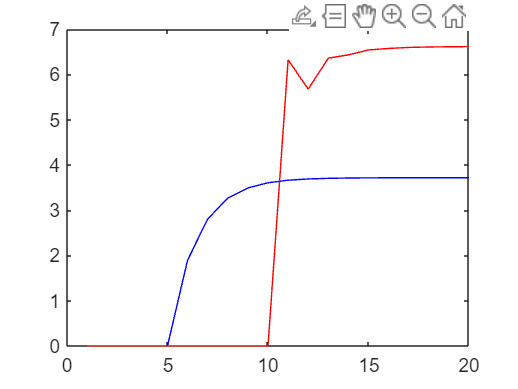

%sys2 = arx(z2,[na nb nk])

%%%% Plot arx model created 
%%%%QUESTION: is it possible to graph 

plot(y1,'b-')

hold all

plot(y2,'r-')
hold off


plot(u1,'b-')

hold all

plot(u2,'r-')


%sys_nl = nlarx(z,[na nb nk])
%nlarxPlot(sys_nl)

# Utilizing Python Gekko Package


import pip.*
py.pip.main(py.list({'install','gekko'}))

Python commands require a supported version of CPython.

Related documentation


%%%Install Gekko package and call GEKKO object
m = py.gekko.GEKKO()

import pandas.*

%%%% Setup of variables
url = 'http://apmonitor.com/do/uploads/Main/tclab_2sec.txt'
websave('data_arx', url);
arx_data = readtable('data_arx');
t = arx_data.Time
u = [arx_data.H1, arx_data.H2]
y = [arx_data.T1, arx_data.T2]


%%%% system identification
na = 2 %%% output coefficients
nb = 2 %%% input coefficients

[yp, p, K] = m.sysid(t,u,y,na,nb,objf=10000,scale=false,diaglevel=1)
